## Lab 1 - Simulation

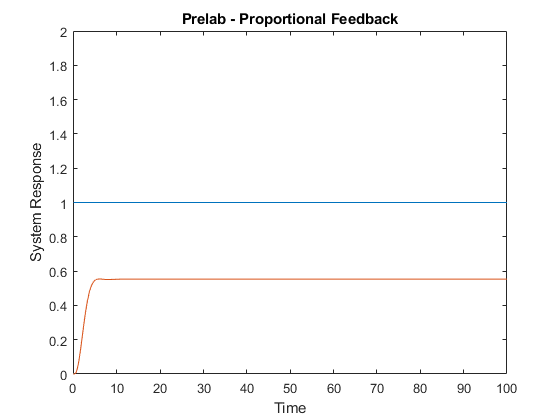

load("dataset021.mat");
sim('Lab1_Prelab.slx');
load("PreL1_Out.mat");

plot(PreL1_Out.signal1);
hold on;
plot(PreL1_Out.signal2);
hold off;
axis([-0.1 100 0 2]);
xlabel("Time");
ylabel("System Response");
title("Prelab - Proportional Feedback");

### Part 1 - P

Kp_P.Value = 14.4131;
sim('Lab1_P.slx');
load("L1_P_Out.mat");

G_P = G1 * G2 * Kp_P.Value;
Gcl_P = G_P / (1 + G_P);
Z = roots(Gcl_P.Denominator{1,1});
W_P = Z(ceil(length(Z)/2))

W_P = -0.0000 + 1.4428i

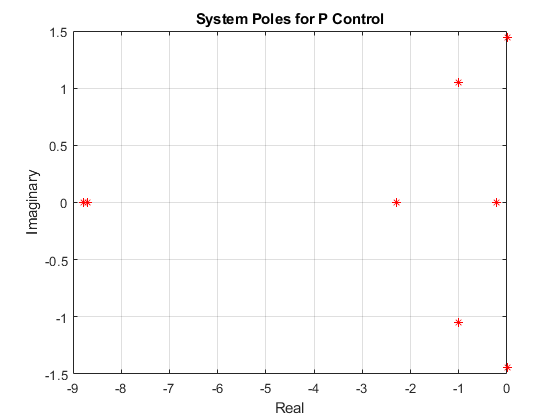

plot(real(Z), imag(Z), '*r');
grid on;
title("System Poles for P Control");
xlabel("Real");
ylabel("Imaginary");

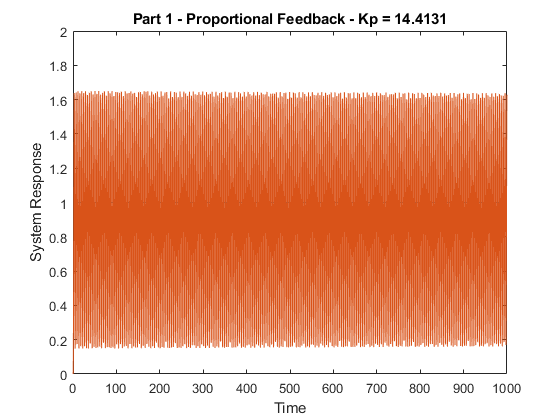


plot(L1_P_Out.signal1);
hold on;
plot(L1_P_Out.signal2);
hold off;
axis([-0.1 1000 0 2]);
xlabel("Time");
ylabel("System Response");
title("Part 1 - Proportional Feedback - Kp = 14.4131");

### Part 2 - PI

Kp_PI.Value = 0.3685;
Ki.Value = 5;
sim('Lab1_PI.slx');
load("L1_PI_Out.mat");

G_PI = G1 * G2 * Kp_PI.Value*(1 + Ki.Value);
Gcl_PI = G_PI / (1 + G_PI);
Z = roots(Gcl_PI.Denominator{1,1})

Z =   -8.7720 + 0.0000i
  -8.7610 + 0.0000i
  -1.0000 + 1.0488i
  -1.0000 - 1.0488i
  -0.6784 + 0.9094i
  -0.6784 - 0.9094i
  -0.8821 + 0.0000i
  -0.2280 + 0.0000i


W_PI = Z(ceil(length(Z)/2)+1)

W_PI = -0.6784 + 0.9094i

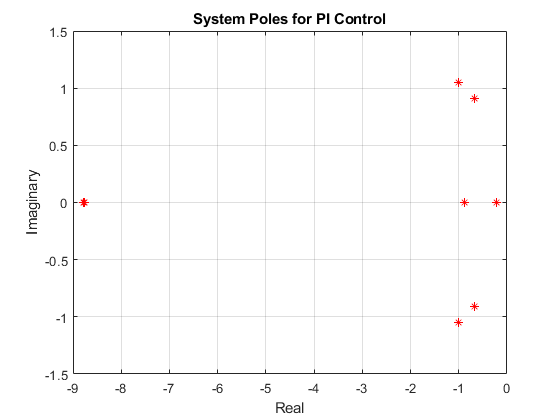

plot(real(Z), imag(Z), '*r');
grid on;
title("System Poles for PI Control");
xlabel("Real");
ylabel("Imaginary");

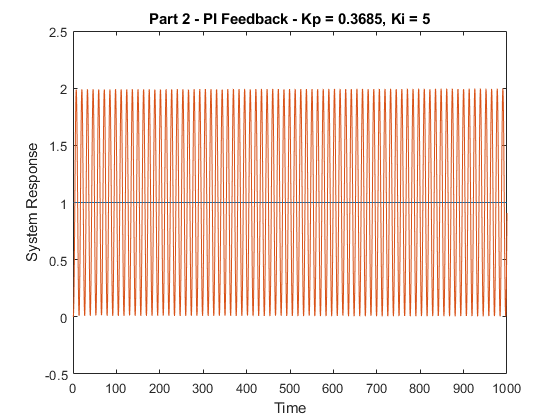


plot(L1_PI_Out.signal1);
hold on;
plot(L1_PI_Out.signal2);
hold off;
axis([-0.1 1000 -0.5 2.5]);
xlabel("Time");
ylabel("System Response");
title("Part 2 - PI Feedback - Kp = 0.3685, Ki = 5");


Kp_PD.Value = 4.7905;
Kd.Value = 2;
sim('Lab1_PD.slx');
load("L1_PD_Out.mat");

G_PD = G1 * G2 * Kp_PD.Value*(1 + Kd.Value);
Gcl_PD = G_PD / (1 + G_PD);
Z = roots(Gcl_PD.Denominator{1,1});
W_PD = Z(ceil(length(Z)/2))

W_PD = -0.0010 + 1.4417i

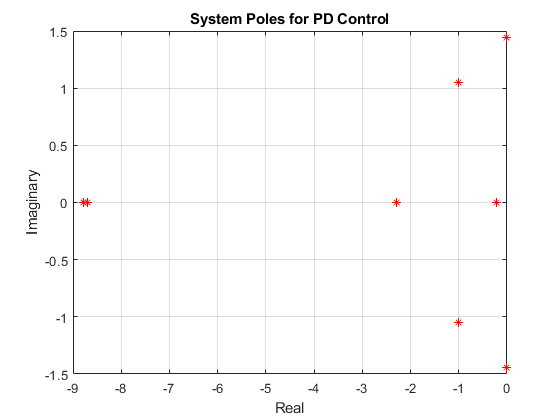

plot(real(Z), imag(Z), '*r');
grid on;
title("System Poles for PD Control");
xlabel("Real");
ylabel("Imaginary");

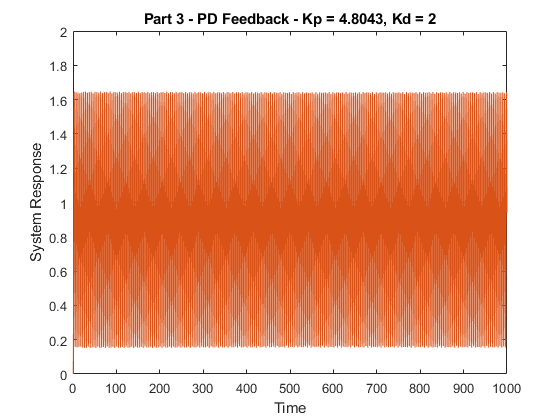


plot(L1_PD_Out.signal1);
hold on;
plot(L1_PD_Out.signal2);
hold off;
axis([-0.1 1000 0 2]);
xlabel("Time");
ylabel("System Response");
title("Part 3 - PD Feedback - Kp = 4.8043, Kd = 2");